# Heat flow on a dumbbell graph

Solve the heat equation 


$$u_t = \triangle u$$


on a dumbbell graph.

The standard Crank-Nicholson method with time step $h$ is:

$\left(I - \frac{h}{2}\triangle\right)u_{k+1} = 
 \left(I +\frac{h}{2}\triangle\right) u_k$.

We must modify that to ensure that $u_{k+1}$ satisfies the discrete vertex conditions. In the notation of the paper we let

$\mathbf{L}_+ = {\mathbf{P}_{0} + \frac{h}{2} \mathbf{L}_{0}

$ and $\mathbf{L}_-  = \mathbf{P}_{\rm VC} - \frac{h}{2} \mathbf{L}_{\rm VC}$

and then iterate

$\mathbf{L}_{-} u_{k+1} = \mathbf{L}_{+} u_k$.

## Set up the graph and the initial condition

G=quantumGraphFromTemplate('dumbbell');%,'Discretization','Chebyshev',nx=64);
f0=@(x)(2-2*cos(x-pi/3));
f1=1;
f2=@(x)cos(x);
y=G.applyFunctionsToAllEdges({f0,f1,f2});

## Set up the time stepping

h=0.05;
tPlot=0.5;
tFinal=10;
nSkip=tPlot/h;
nStep=tFinal/h;

## Set up places to save data

t=0:tPlot:tFinal;
nSave=length(t);
Y=zeros(length(y),nSave);
totalHeatVector=zeros(size(t));
totalHeatVector(1)=G.integral(y);

## Set up the evolution matrices

L0 = G.laplacianMatrixWithZeros;
P0 = G.interpolationMatrixWithZeros;
LVC = G.laplacianMatrixWithVC;
PVC = G.interpolationMatrixWithVC;
LPlus =  P0  + (h/2)*L0;
LMinus = PVC - (h/2)*LVC;

## Evolve  the solution

keepCount=1;
Y(:,1)=y;
for k=1:nStep
    y = LPlus*y;
    y = LMinus\y;
    if mod(k,nSkip)==0
        keepCount=keepCount+1;
        Y(:,keepCount)=y;
        totalHeatVector(keepCount)= G.integral(y);
    end
end

## Show that the total heat is conserved

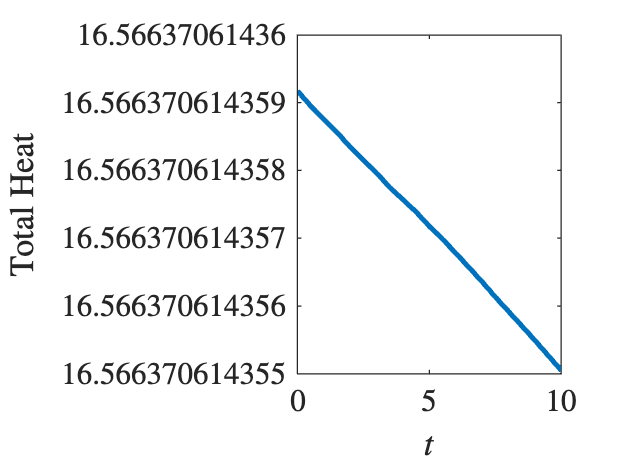

plot(t,totalHeatVector)
xlabel('$t$')
ylabel('Total Heat')

fprintf('Change in heat is %0.2e',max(totalHeatVector)-min(totalHeatVector))

Change in heat is 4.12e-12

## Animate the solution

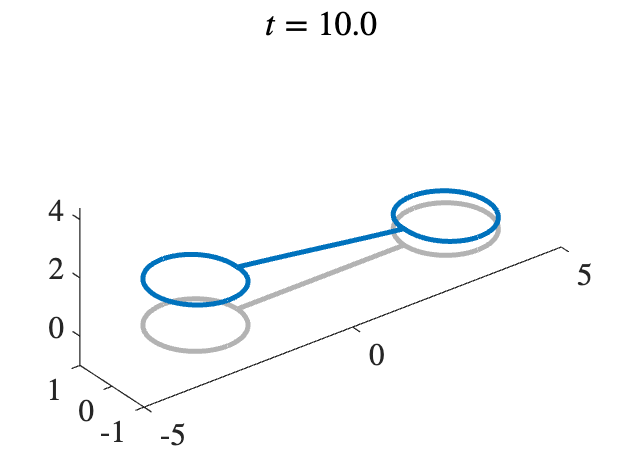

G.animatePDESolution(Y,t);

## Double the temporal resolution twice

yFinal=zeros(length(y),3);
yFinal(:,1)=y;
for j=2:3
    h = h/2;
    LPlus =  P0  + (h/2)*L0;
    LMinus = PVC - (h/2)*LVC;
    nStep=tFinal/h;
    y=G.applyFunctionsToAllEdges({f0,f1,f2});
    for k=1:nStep
        y = LPlus*y;
        y = LMinus\y;
    end
    yFinal(:,j)=y;
end

## Calculate the error ratio

yDiff=diff(yFinal,1,2);
error1=G.norm(yDiff(:,1))

error1 =        1/2238402


error2=G.norm(yDiff(:,2))

error2 =        1/8658541


errorRatio= error1/error2

errorRatio =      851/220   
